## Wing Design

cruise = AirCondition()

cruise =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise.M = 0.8;
cruise.h = convlength(39000, 'ft','m');

## 1.Design CL

CLdes = W0_Sref_cruise/(1/2*cruise.rho*cruise.V^2)

Unrecognized function or variable 'W0_Sref_cruise'.

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

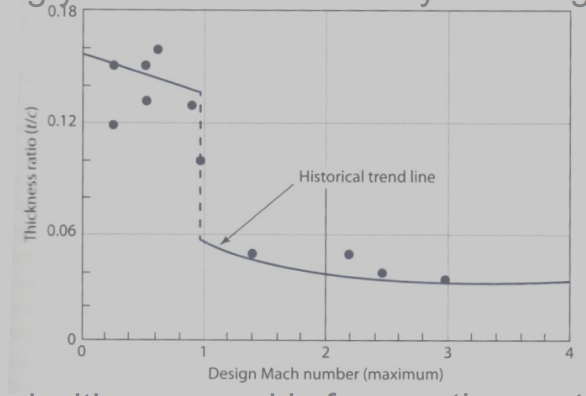

### Conclusion:

polarName = "xf-sc21010-il-1000000.csv";
shapeName = "sc21010.dat.txt";

## 3.Shape

1.Use MDO to get best geometry

    -Make sure it is applicable to double-tapered, swept wing

    -At each iteration inside MDO, calculate the optimum twist to give elliptical lift distribution

    -Use a validated wing weight estimation model

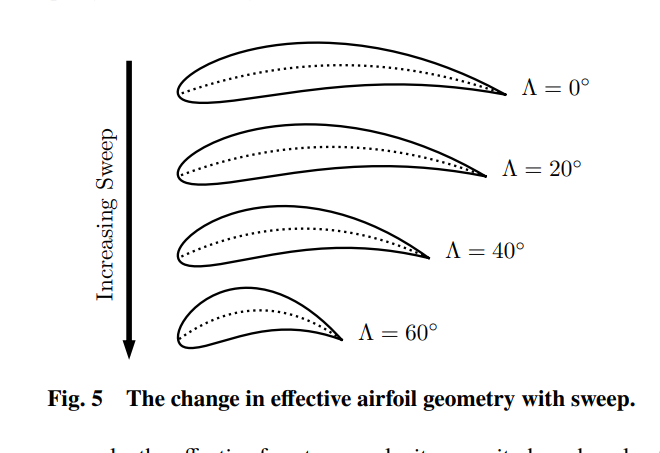

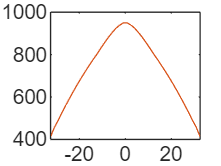

Process is complete! Converged circulation distribution found.


Error using WingGeometry/Lambdax_c (line 51)
Input y = -32.175000 is outside the wing semi-span [0, 32.500000]

Error in CDWfun (

% Initial guess
% wing span fixed to 65, root chord fixed to 12m.
cr = 12;
b = 65;
x0 = [8, 3, 31*pi/180, 25*pi/180, 12, deg2rad(2)];
%x0 = [yk, yt, Lambdain50, Lambdaout50, yk, maxtwist in radians]
% Design variables bounds
lb = x0.*0.5;
ub = x0.*2;
wing0 = x02wing(x0, 12, 65/2);


% Optimization options
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
% Run the optimization
[x_opt, fval] = fmincon(@wingMDO, x0, [], [], [], [], lb, ub, @constraintFunction, options);

wing_opt = x02wing(x_opt, 12, 65/2);
figure(1)
clf;
subplot(2,1,1)
wing0.plotWing()
title("Initial")
axis equal
subplot(2,1,2)
wing_opt.plotWing()
title("Optimzed")
axis equal
wing_opt

## 4.Dihedral

-G17 presents a quantitative estimate

## 5.HLD

1.Calculate CLmax requirement at landing and takeoff

2.Select

## 6.Control Surfaces

## 7.Tailplane design

## 8.Nose shape optimization